fileNames = { % text file 읽어오기
    '통합실험 8차(08.15)\raw_data\exo_off-000_00B4BB4F.txt', 'data_foot', 'foot_exo_off';
    '통합실험 8차(08.15)\raw_data\exo_off-000_00B4BB4E.txt', 'data_shank', 'shank_exo_off';
    '통합실험 8차(08.15)\raw_data\exo_off-000_00B4BB52.txt', 'data_FOOT', 'foot_exo_on';
    '통합실험 8차(08.15)\raw_data\exo_off-000_00B4BAF3.txt', 'data_SHANK', 'shank_exo_on';
};

fields = {'PacketCounter', 'acc_x', 'acc_y', 'acc_z', 'gyro_x', 'gyro_Y', 'gyro_Z', 'roll', 'pitch', 'yaw'};

for i = 1:size(fileNames, 1)
    fileID = fopen(fileNames{i, 1}, 'r');
    data = textscan(fileID, '%d %f %f %f %f %f %f %f %f %f', 'HeaderLines', 13);
    fclose(fileID);
    assignin('base', fileNames{i, 2}, data);

    dataStruct = struct(); %구조체 할당
    for j = 1:length(fields) % 각 field 에 저장
        dataStruct.(fields{j}) = data{j};
    end
    assignin('base', fileNames{i, 3}, dataStruct);
end


% Butterworth Filter
%과학적 연구를 위해서는 EMF 전체 대역에 해당하는 10~ 500 Hz 대역을 측정하기를 권장
Fs = 1000; % Sampling frequency in Hz 
% Order of the Butterworth filter : 차원 높이면 phase shift phenomenon 감소
order = 4; 
% Cutoff frequency in Hz: cutoff frequency 이상의 신호 성분 감쇠- 일반적으로 emg는 40 ~ 50 
cutoff = 10; 
% Design Butterworth filter
[b, a] = butter(order, cutoff/(Fs/2));
foot_exo_off.acc_x = filtfilt(b, a, foot_exo_off.acc_x); %양방향 filtering
foot_exo_off.acc_y = filtfilt(b, a, foot_exo_off.acc_y); %양방향 filtering
foot_exo_off.acc_z = filtfilt(b, a, foot_exo_off.acc_z); %양방향 filtering
shank_exo_off.acc_x = filtfilt(b, a, shank_exo_off.acc_x); %양방향 filtering
shank_exo_off.acc_y = filtfilt(b, a, shank_exo_off.acc_y); %양방향 filtering
shank_exo_off.acc_z = filtfilt(b, a, shank_exo_off.acc_z); %양방향 filtering

foot_exo_on.acc_x = filtfilt(b, a, foot_exo_on.acc_x); % 양방향 filtering
foot_exo_on.acc_y = filtfilt(b, a, foot_exo_on.acc_y); % 양방향 filtering
foot_exo_on.acc_z = filtfilt(b, a, foot_exo_on.acc_z); % 양방향 filtering
shank_exo_on.acc_x = filtfilt(b, a, shank_exo_on.acc_x); % 양방향 filtering
shank_exo_on.acc_y = filtfilt(b, a, shank_exo_on.acc_y); % 양방향 filtering
shank_exo_on.acc_z = filtfilt(b, a, shank_exo_on.acc_z); % 양방향 filtering


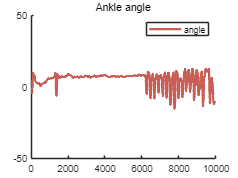

% Function to calculate pitch angle from accelerometer data
calculate_pitch = @(acc_x, acc_y, acc_z) atan2(sqrt(acc_x.^2 + acc_y.^2), acc_z ) * (180/pi);

% Calculate pitch angles for foot, shank, and thigh
theta_foot_off = calculate_pitch(foot_exo_off.acc_x, foot_exo_off.acc_y, foot_exo_off.acc_z);
theta_shank_off = calculate_pitch(shank_exo_off.acc_x, shank_exo_off.acc_y, shank_exo_off.acc_z);


windowSize = 10;
movingAvg = movmean(theta_foot_off, windowSize);

% 이상치 탐색 (원래 데이터와 이동 평균의 차이가 크면 이상치로 간주)
threshold = 1; % 임계값 설정
theta_foot_off(abs(theta_foot_off - movingAvg) > threshold) = NaN;% 이상치를 NaN으로 치환
theta_foot_off = fillmissing(theta_foot_off, 'linear');% 이상치를 보간하여 대체 (선형 보간법 사용)

movingAvg = movmean(theta_shank_off, windowSize);
theta_shank_off(abs(theta_shank_off - movingAvg) > threshold) = NaN;% 이상치를 NaN으로 치환
theta_shank_off = fillmissing(theta_shank_off, 'linear');% 이상치를 보간하여 대체 (선형 보간법 사용)


% Calculate ankle and knee angles
ankle_angle_off = theta_shank_off - theta_foot_off;

% Calculate the mean of the first 10 values
ankle_angle_off_mean = mean(ankle_angle_off(1:10));
%knee_angle_off_mean = mean(knee_angle_off(1:10));

% Subtract the mean from each angle
ankle_angle_off = ankle_angle_off - ankle_angle_off_mean;
movingAvg = movmean(ankle_angle_off, windowSize);
ankle_angle_off(abs(ankle_angle_off - movingAvg) > threshold) = NaN;% 이상치를 NaN으로 치환
ankle_angle_off = fillmissing(ankle_angle_off, 'linear');% 이상치를 보간하여 대체 (선형 보간법 사용)

ankle_angle_off=interp1(1:length(ankle_angle_off),ankle_angle_off, linspace(1,length(ankle_angle_off),10000),'linear')';

start_t=0;
end_t=length(ankle_angle_off);

figure; 
hold on;
%plot(foot_exo_off.acc_x, 'LineStyle','-','Color',[0/255,0/255,0/255],LineWidth=2.3);
%plot(foot_exo_off.acc_y, 'LineStyle','-','Color',[100/255,100/255,100/255],LineWidth=2.3);
plot( ankle_angle_off, 'LineStyle','-','Color',[201/255,94/255,86/255],LineWidth=2.3);
xlim([start_t,end_t]);
ylim([-50,50])
title('Ankle angle')
legend('angle')
hold off;

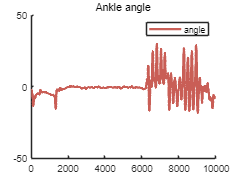

calculate_pitch = @(acc_x, acc_y, acc_z) atan2(sqrt(acc_x.^2 + acc_y.^2), acc_z ) * (180/pi);

% Calculate pitch angles for foot, shank, and thigh
theta_foot_on = calculate_pitch(foot_exo_on.acc_x, foot_exo_on.acc_y, foot_exo_on.acc_z);
theta_shank_on = calculate_pitch(shank_exo_on.acc_x, shank_exo_on.acc_y, shank_exo_on.acc_z);


windowSize = 10;
movingAvg = movmean(theta_foot_on, windowSize);

% 이상치 탐색 (원래 데이터와 이동 평균의 차이가 크면 이상치로 간주)
threshold = 1; % 임계값 설정
theta_foot_on(abs(theta_foot_on - movingAvg) > threshold) = NaN;% 이상치를 NaN으로 치환
theta_foot_on = fillmissing(theta_foot_on, 'linear');% 이상치를 보간하여 대체 (선형 보간법 사용)

movingAvg = movmean(theta_shank_on, windowSize);
theta_shank_on(abs(theta_shank_on- movingAvg) > threshold) = NaN;% 이상치를 NaN으로 치환
theta_shank_on = fillmissing(theta_shank_on, 'linear');% 이상치를 보간하여 대체 (선형 보간법 사용)


% Calculate ankle and knee angles
ankle_angle_on = theta_shank_on - theta_foot_on;

% Calculate the mean of the first 10 values
ankle_angle_on_mean = mean(ankle_angle_on(1:10));
%knee_angle_off_mean = mean(knee_angle_off(1:10));

% Subtract the mean from each angle
ankle_angle_on = ankle_angle_on - ankle_angle_on_mean;
movingAvg = movmean(ankle_angle_on, windowSize);
ankle_angle_on(abs(ankle_angle_on - movingAvg) > threshold) = NaN;% 이상치를 NaN으로 치환
ankle_angle_on = fillmissing(ankle_angle_on, 'linear');% 이상치를 보간하여 대체 (선형 보간법 사용)

ankle_angle_on=interp1(1:length(ankle_angle_on),ankle_angle_on, linspace(1,length(ankle_angle_on),10000),'linear')'-3;

figure; 
hold on;
%plot(foot_exo_off.acc_x, 'LineStyle','-','Color',[0/255,0/255,0/255],LineWidth=2.3);
%plot(foot_exo_off.acc_y, 'LineStyle','-','Color',[100/255,100/255,100/255],LineWidth=2.3);
plot( ankle_angle_on, 'LineStyle','-','Color',[201/255,94/255,86/255],LineWidth=2.3);
xlim([start_t,end_t]);
ylim([-50,50])
title('Ankle angle')
legend('angle')
hold off;

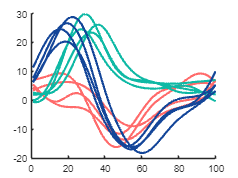

%1) 보행 환경에 따라 데이터 분할
idx= [6534,7394,8239,9118]; % initial, IC, LG,DC


%40bpm: 60/40bpm -> 1.5초 (out.time: 150) 에 한 번씩 보행
sections = {'IC',  'LG', 'DC'};
sections2 = {'IC_off',  'LG_off', 'DC_off'};

for i = 1:length(sections)
    eval([sections{i} ' = ankle_angle_on(idx(i):idx(i + 1) - 1, :);']);
    eval([sections2{i} ' = ankle_angle_off(idx(i):idx(i + 1) - 1, :);']);
end


%2) 데이터 보간
env = {'LG', 'IC', 'DC','IC_off',  'LG_off', 'DC_off'};
interpolate_data(env, 400);%보간할 데이터 포인트 수 -> 100 * 3 cycle
% gait cycle 별로 segmentation 수행
% 배열 재구성
for i = 1:length(env)
    eval([env{i} ' = reshape(' env{i} ', 100, 4);']);
end
figure;
hold on;
plot(LG,  'Color',[255/255, 107/255, 107/255], 'LineWidth', 2);
plot(IC, 'Color',[15/255, 185/255, 165/255], 'LineWidth', 2); %red
plot(DC, 'Color', [20/255, 70/255, 153/255], 'LineWidth', 2); %blue
hold off;

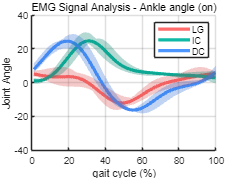



%Average Plotting

figure;
hold on;

plot(mean(LG,2), 'Color', [255/255, 107/255, 107/255], 'LineWidth', 3); %red
plot(mean(IC,2), 'Color',[15/255, 185/255, 165/255], 'LineWidth',3); %green
plot(mean(DC,2), 'Color', [77/255, 150/255, 255/255], 'LineWidth', 3); %blue

plot_shade(LG, [215/255, 77/255, 77/255]); %r
plot_shade(IC, [5/255, 130/255, 110/255]); %g
plot_shade(DC, [47/255, 110/255, 215/255]); %b

xlabel('gait cycle (%)');
ylabel('Joint Angle');
title('EMG Signal Analysis - Ankle angle (on)');
legend('LG','IC','DC')

grid on
ylim([-40, 40]);
hold off;

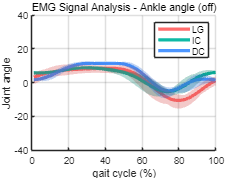


figure;
hold on;

plot(mean(LG_off,2), 'Color', [255/255, 107/255, 107/255], 'LineWidth', 3); %red
plot(mean(IC_off,2), 'Color',[15/255, 185/255, 165/255], 'LineWidth',3); %green
plot(mean(DC_off,2), 'Color', [77/255, 150/255, 255/255], 'LineWidth', 3); %blue

plot_shade(LG_off, [215/255, 77/255, 77/255]); %r
plot_shade(IC_off, [5/255, 130/255, 110/255]); %g
plot_shade(DC_off, [47/255, 110/255, 215/255]); %b

xlabel('gait cycle (%)');
ylabel('Joint angle');
title('EMG Signal Analysis - Ankle angle (off)');
legend('LG','IC','DC')

grid on
ylim([-40, 40]);
hold off;

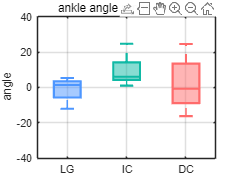

data = [mean(LG,2), mean(IC,2), mean(DC,2)];
labels = {'LG', 'IC', 'DC'};

% 상자 그림 생성
figure;
boxplot(data, 'Labels', labels, 'Whisker', 1.5);

% 그래프 설정
ylabel('angle', 'FontSize', 10); % y축 레이블 폰트 크기 조정
title('ankle angle range : exo off', 'FontSize', 20); % 타이틀 폰트 크기 조정
set(gca, 'FontSize', 10);
ylim([-40, 40]);

% 스타일 설정 (상자 색상 변경)
h = findobj(gca, 'Tag', 'Box');
colors = [
    [255/255, 107/255, 107/255];    % red for without exo
    [15/255, 185/255, 165/255];    % green for exo off
     [77/255, 150/255, 255/255]     % blue for exo on
];
edge_colors = { [255/255, 107/255, 107/255],  [15/255, 185/255, 165/255],  [77/255, 150/255, 255/255] }; % 빨강, 초록, 파랑
grid on;
for j = 1:length(h)
    patch(get(h(j), 'XData'), get(h(j), 'YData'), colors(j,:), 'FaceAlpha', .5,'EdgeColor',edge_colors{j},'linewidth',2);
end

% 중간선 색상 변경
median_lines = findobj(gca, 'Tag', 'Median');
median_colors = [
    [255/255, 107/255, 107/255];    % blue for without exo
    [15/255, 185/255, 165/255];    % green for exo off
   [77/255, 150/255, 255/255]     % red for exo on
];
for k = 1:length(median_lines)
    median_lines(k).Color = median_colors(k, :);
    median_lines(k).LineWidth=2;
end


% lower shadow, higher shadow 선 색상 변경
lower_whisker = findobj(gca, 'Tag', 'Lower Whisker');
upper_whisker = findobj(gca, 'Tag', 'Upper Whisker');
lower_adjacent = findobj(gca, 'Tag', 'Lower Adjacent Value');
upper_adjacent = findobj(gca, 'Tag', 'Upper Adjacent Value');
for k = 1:length(lower_whisker)
    lower_whisker(k).Color = median_colors(k, :);
    upper_whisker(k).Color = median_colors(k, :);
    lower_adjacent(k).Color = median_colors(k, :);
    upper_adjacent(k).Color = median_colors(k, :);
    lower_adjacent(k).LineWidth=2;
    upper_whisker(k).LineWidth=2;
    lower_adjacent(k).LineWidth=2;
    upper_adjacent(k).LineWidth=2;
end

overbar(1,2,30,'***');

'overbar'은(는) 인식할 수 없는 함수 또는 변수입니다.

overbar(2,3,40,'***');
overbar(1,3,50,'***');
grid on;
hold off;

exo_off=struct('LG',LG,'IC',IC,'DC',DC,'LG_off',LG_off,'IC_off',IC_off,'DC_off',DC_off)

exo_off = 다음 필드를 포함한 struct :
        LG: [100×4 double]
        IC: [100×4 double]
        DC: [100×4 double]
    LG_off: [100×4 double]
    IC_off: [100×4 double]
    DC_off: [100×4 double]


function interpolate_data(data_names, num_points)
    % 데이터 보간 함수
    % data_names: 변수 이름을 담고 있는 셀 배열
    % num_points: 보간 후의 데이터 포인트 수
    
    for i = 1:length(data_names)
        % 원본 데이터 가져오기
        data = evalin('base', data_names{i});
        
        % 보간
        interpolated_data = interp1(1:numel(data), data, linspace(1, numel(data), num_points), 'linear');
        
        % 변수 업데이트
        assignin('base', data_names{i}, interpolated_data);
    end
end
function plot_shade(data, color)
    % 데이터의 평균과 최소, 최대 값을 계산
    mean_data = mean(data, 2);
    min_data = min(data, [], 2);
    max_data = max(data, [], 2);
    
    % x축 데이터 정의
    x = 1:length(mean_data);

    % 쉐이딩 플롯
    fill([x fliplr(x)], [min_data' fliplr(max_data')], color, 'FaceAlpha', 0.3, 'EdgeColor', 'none');
end